% setables
grp_size = 30; % size of each group in training
test_grp_size = 30; % size of each group in test
LEAVE_IN = 10; % number of features for each mini-classifier to use  %%%% number of miniclassifiers
NB = 1; % number of bags
random_seed = 3; % random seed

% random number generator
rs = rng(random_seed);

% set up features
mu_uncorr   = [2.0, 2.0]; % two features that are uncorrelated with expression difference of 2.5
mu_corr     = [2.0, 2.0]; % two features that are corrlated with expression difference of 2.0
NF_informative = length(mu_corr) + length(mu_uncorr);
corr_sample_std = 0.5; % standard deviation of distribution to sample when generating off diagonal elements of correlation matrix 
NF_uninformative = 2*LEAVE_IN - NF_informative; % four uninformative features (expression difference of 0)

% derivables from what we've set, but used downstairs

NF = NF_uninformative + NF_informative;

% setables, but by default are derivable from things we've already set
NS_training = 2*grp_size; % the number of training samples
NMCS = NF*(NF+1)*0.5; % number of mini-classifiers
NDOI = 10*floor(NMCS/LEAVE_IN); % number of drop-out iterations

% set up the correlation matrices
lambda = find_parm_random_corr(corr_sample_std); 
corr_mat = [];
if (length(mu_corr) > 1)
    corr_mat = vineBeta(length(mu_corr),lambda);
end

% generate training and validation sample
[r1,r2,rs] = GenReal_for_SV(grp_size, grp_size, NF, mu_uncorr, mu_corr, corr_mat, corr_mat, rs);
[t1,t2,rs] = GenReal_for_SV(grp_size, grp_size, NF, mu_uncorr, mu_corr, corr_mat, corr_mat, rs);

% turn it into tables and name the feautres
varNames = cell(NF,1);
for i = 1:NF
    if( i <= (NF-NF_informative)) % uninformative
        varNames{i} = ['U' num2str(i)];
    elseif ( i > NF - length(mu_corr)) % informative correlated
        varNames{i} = ['IC' num2str(i)];
    else
        varNames{i} = ['IU' num2str(i)]; % informative uncorrelated
    end
end
R = array2table( [r1 ; r2],'VariableNames',varNames);
T = array2table( [t1 ; t2],'VariableNames',varNames);

% make training labels and test labels
trainingLabels(1:grp_size) = 1;
trainingLabels(grp_size+1:NS_training) = 0;
testLabels(1:test_grp_size) = 1;
testLabels((test_grp_size+1): (2*test_grp_size)) = 0;
ftr_table = addvars(R,trainingLabels','NewVariableNames','Labels');

% train the dxCortex model
tic;
fullCortex = dxCortex_pairs(NB,rs,NDOI,LEAVE_IN,7); % NOTE pick different RS for different mus !!!!
fullCortex.train(ftr_table,0.6666666);
train_time = toc

train_time =    3.455059100000000




% get prediction on test set
labels = fullCortex.predict(T);
test_accuracy = 1 - sum ( (labels > 0.5) ~= testLabels' )  /size(T,1);
display([ 'test-accuracy = ' num2str(test_accuracy) ])

test-accuracy = 0.98333



% % get all four types of Shapley values from the paper
% tic;
% [SVs_restricted,~,~] = fullCortex.SVs_restricted(T);
% restricted_time = toc
% 
% tic;
% [SVs_shallow,~,~] = fullCortex.SVs_shallow(T);
% shallow_time = toc

time_features = [ 8 10 12 14 16 18 20];
i_time = 7;
% deep_time = zeros(7,1);
% hier_time = zeros(7,1);
% NO_time = zeros(7,1);
% HNO_time = zeros(7,1);
% NL_time = zeros(7,1);
% HNL_time = zeros(7,1);

unit_scale = 1/(NDOI*size(T,1));

tic;
[SVs_deep,~,~] = fullCortex.SVs_deep(T);
deep_time(i_time) = toc * unit_scale

deep_time =    0.000069446351852
   0.000149946681818
   0.000344886487179
   0.000842283788889
   0.002433004970588
   0.005844425166667
   0.015764585190476



tic;
[SVs_hierarchical,~,~] = fullCortex.SVs_hierarchical(T);
hier_time(i_time) = toc* unit_scale

hier_time = 1.0e-03 *

   0.037424759259259
   0.053055393939394
   0.082524782051282
   0.138019566666667
   0.240739529411765
   0.446582464912281
   0.856047468253968



% tic;
% [SVs_LS,~,~] = fullCortex.SVs_LS(T);
% LS_time = toc

tic;
[SVs_NO,~,~] = fullCortex.SVs_NO(T);
NO_time(i_time) = toc* unit_scale

NO_time =    0.000163133074074
   0.000270982575758
   0.000474230705128
   0.000812363233333
   0.001541095549020
   0.002426968754386
   0.003949661269841



tic;
[SVs_HNO,~,~] = fullCortex.SVs_HNO(T);
HNO_time(i_time) = toc* unit_scale

HNO_time =    0.000084553703704
   0.000124877106061
   0.000193830461538
   0.000299220111111
   0.000504400000000
   0.000750555035088
   0.001167816579365



tic;
[SVs_NL,~,~] = fullCortex.SVs_NL(T);
NL_time(i_time) = toc* unit_scale

NL_time = 1.0e-03 *

   0.094631259259259
   0.132172651515152
   0.177731628205128
   0.250012933333333
   0.356352852941176
   0.459664342105263
   0.609550380952381


tic;
[SVs_HNL,~,~] = fullCortex.SVs_HNL(T);
HNL_time(i_time) = toc* unit_scale

HNL_time = 1.0e-03 *

   0.070674296296296
   0.090616484848485
   0.120593358974359
   0.157064566666667
   0.219406049019608
   0.274813631578947
   0.356488460317460


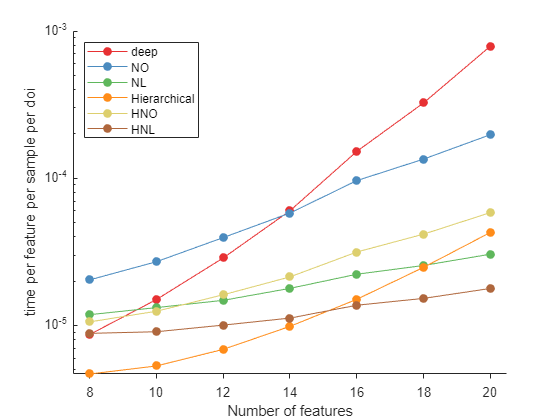


%PLOT TIMING DATA

clf("reset")
xs = time_features;
C = linspecer(6);
hold on
xticks(xs)
%xticklabels(varNames);
plot(xs,deep_time' ./ xs,'-o','Color',C(1,:),"MarkerFaceColor",C(1,:),'DisplayName','deep')
plot(xs,NO_time' ./ xs,'-o','Color',C(2,:),"MarkerFaceColor",C(2,:),'DisplayName','NO')
plot(xs,NL_time' ./ xs,'-o','Color',C(3,:),"MarkerFaceColor",C(3,:),'DisplayName','NL')
plot(xs,hier_time' ./ xs,'-o','Color',C(4,:),"MarkerFaceColor",C(4,:),'DisplayName','Hierarchical')
plot(xs,HNO_time' ./ xs,'-o','Color',C(5,:),"MarkerFaceColor",C(5,:),'DisplayName','HNO')
plot(xs,HNL_time' ./ xs,'-o','Color',C(6,:),"MarkerFaceColor",C(6,:),'DisplayName','HNL')
xlabel('Number of features')
ylabel('time per feature per sample per doi')
legend('Location',"northwest")
xlim([7.5 20.5])
%ylim([-0.2 0.5])
ax = gca;
ax.YScale = "log";
ax.XAxis.TickDirection = 'out';
hold off


% plot the Shapley values like in figure 2 from the paper
%SVS_r = [SVs_restricted(:,1:grp_size) -1*SVs_restricted(:,grp_size+1:end)];
%SVS_s = [SVs_shallow(:,1:grp_size) -1*SVs_shallow(:,grp_size+1:end)];
SVS_d = [SVs_deep(:,1:grp_size) -1*SVs_deep(:,grp_size+1:end)];
SVS_h = [SVs_hierarchical(:,1:grp_size) -1*SVs_hierarchical(:,grp_size+1:end)];
SVS_NL = [SVs_NL(:,1:grp_size) -1*SVs_NL(:,grp_size+1:end)];
SVS_HNL= [SVs_HNL(:,1:grp_size) -1*SVs_HNL(:,grp_size+1:end)];
SVS_NO = [SVs_NO(:,1:grp_size) -1*SVs_NO(:,grp_size+1:end)];
SVS_HNO = [SVs_HNO(:,1:grp_size) -1*SVs_HNO(:,grp_size+1:end)];
%SVS_LS = [SVs_LS(:,1:grp_size) -1*SVs_LS(:,grp_size+1:end)];

ff = 1./sqrt(size(SVS_d,2));
d_vals = mean(SVS_d,2);
d_err = std(SVS_d,1,2)*ff;
h_vals = mean(SVS_h,2);
h_err = std(SVS_h,1,2)*ff;
% s_vals = mean(SVS_s,2);
% s_err = std(SVS_s,1,2)*ff;
% r_vals = mean(SVS_r,2);
% r_err = std(SVS_r,1,2)*ff;
NL_vals = mean(SVS_NL,2);
NL_err = std(SVS_NL,1,2)*ff;
NO_vals = mean(SVS_NO,2);
NO_err = std(SVS_NO,1,2)*ff;
HNL_vals = mean(SVS_HNL,2);
HNL_err = std(SVS_HNL,1,2)*ff;
HNO_vals = mean(SVS_HNO,2);
HNO_err = std(SVS_HNO,1,2)*ff;
%LS_vals = mean(SVS_LS,2);
%LS_err = std(SVS_LS,1,2)*ff;

clf("reset")
xs =1:1:length(d_vals);
C = linspecer(6);
hold on
%errorbar(xs,r_vals,r_err,'o','Color',C(1,:),"MarkerFaceColor",C(1,:),'DisplayName','restricted')
%errorbar(xs,s_vals,s_err,'o','Color',C(2,:),"MarkerFaceColor",C(2,:),'DisplayName','shallow')
errorbar(xs,d_vals,d_err,'o','Color',C(3,:),"MarkerFaceColor",C(1,:),'DisplayName','deep')
errorbar(xs,h_vals,h_err,'o','Color',C(4,:),"MarkerFaceColor",C(2,:),'DisplayName','hierarchical')
errorbar(xs,NL_vals,NL_err,'o','Color',C(5,:),"MarkerFaceColor",C(3,:),'DisplayName','nested level')
errorbar(xs,HNL_vals,HNL_err,'o','Color',C(5,:),"MarkerFaceColor",C(4,:),'DisplayName','hier. nested level')
errorbar(xs,NO_vals,NO_err,'o','Color',C(5,:),"MarkerFaceColor",C(5,:),'DisplayName','nested Owen')
errorbar(xs,HNO_vals,HNO_err,'o','Color',C(6,:),"MarkerFaceColor",C(6,:),'DisplayName','hier. nested Owen')
%errorbar(xs,LS_vals,LS_err,'o','Color',C(7,:),"MarkerFaceColor",C(7,:),'DisplayName','level structure')

xticks(xs)
xticklabels(varNames);
xlabel('features')
ylabel('average SV and error')
legend('Location',"northwest")
xlim([0.5 NF+0.5])
ylim([-0.2 0.5])
ax = gca;
ax.XAxis.TickDirection = 'out';
hold off



SS = T(1,:);
[SVs_NL,pall_NL,p0_NL] = fullCortex.SVs_NL(SS);
[SVs_NO,pall_NO,p0_NO] = fullCortex.SVs_NO(SS);
[SVs_LS,pall_LS,p0_LS] = fullCortex.SVs_LS(SS);
[SVs_h,pall_h,p0_h] = fullCortex.SVs_hierarchical(SS);
[SVs_deep,pall_d,p0_d] = fullCortex.SVs_deep(SS);

[SVs_deep,SVs_h,SVs_LS,SVs_NO,SVs_NL]
[sum(SVs_deep),sum(SVs_h),sum(SVs_LS),sum(SVs_NO),sum(SVs_NL)]
[pall_d, pall_h, pall_LS, pall_NO, pall_NL]
[p0_d, p0_h, p0_LS, p0_NO, p0_NL]



master = fullCortex.masters{1};
SS = T(1,:);

% grab a doi

%for doi = 3:3

NF = length(master.features);
NS = size(SS,1);







            % get the mini classifier labels
mc_labels= master.generate_mc_labels_for_data(SS);
            % get the dictionary
mc_labels_dict = containers.Map;
                % loop over all mini-classifiers
                for imc = 1:master.Nmcs
                    ftrs_used = master.mc_ftrs(imc,1:master.mc_ftr_number(imc));
                    key = myfastint2str(sort(ftrs_used));
                    % !!!!!!!!!!!!!!!!!
                    %disp(['imc = ' num2str(imc) ' key = ' key])
                    mc_labels_dict(key) = 2*mc_labels(:,imc) - 1;
                end
% calculate the classification label for this doi               
% the mini_classifiers used in a doi
mcs = master.doi_mcs(doi,:); 
% the coefficients used in a doi
logregs = master.log_regs(doi,:);
full_labels = mc_labels(mcs);
expo_1 = logregs(1) + dot(full_labels, logregs(2:end));
p_1 = 1.0/(1.0+exp( -1.0*expo_1)); 
phi_all_base = 2*p_1-1.0;

% now calculate from coalition function
% get parameters describing a doi from 
            % or from doi_mcs(Ndoi,L) and mc_ftrs(Nmcs,L)
            ftrs_used_in_kNN = zeros(master.L,2);
            N_ftrs_used_in_kNN = zeros(1,master.L);
            for i=1:master.L
                mcIndex = master.doi_mcs(doi,i);
                NF_in_mc = master.mc_ftr_number(mcIndex);
                ftrs_used_in_kNN(i,:) = master.mc_ftrs(mcIndex,1:NF_in_mc);
                N_ftrs_used_in_kNN(i) = NF_in_mc;
            end
            Nmcs    = size(ftrs_used_in_kNN,1);
            P = @(x) 2/(1+exp(-x))-1 ;
            % rescale the coefficients
            % get the log-reg coefficients for this doi and rescale them (working with
            % -1 and +1 rather than 0 and 1
            coeffs          = master.log_regs(doi,:);
            coeffs(1)       = coeffs(1) + 0.5*sum(coeffs(2:end));
            coeffs(2:end)   = 0.5 * coeffs(2:end);
            
            % make a level_structure
            level_structure = LS(ftrs_used_in_kNN,N_ftrs_used_in_kNN);

gc = cell2mat(level_structure.bottomlayer);
[linear] = gen_logreg_argument(gc,ftrs_used_in_kNN,N_ftrs_used_in_kNN,NS,Nmcs,mc_labels_dict,coeffs);
phi_all_coal = arrayfun(P,linear);

disp([' doi: ' num2str(doi) ' phi_all = ' num2str(phi_all_base) ' lin = ' num2str(expo_1) ' v(gc) = ' num2str(phi_all_coal) ' lin = ' num2str(linear)])
